# Exploring the vocal beahvior of bats in the operant box

## First calculating inter-call intervals and explore the distribution

fprintf(1,'*** Gathering Data for timing of vocal activity ***\n')

*** Gathering Data for timing of vocal activity ***


% BasePath = '/Volumes/server_home/users/JulieE/LMC';
BasePath = '/Volumes/Julie4T'

BasePath = '/Volumes/Julie4T'

TimeVocData = cell(10^3,1); % initialize the list to 1000
InterCallInterval = cell(1,10^3);
ExpFolders = dir(fullfile(BasePath,'LMC_Co*'));
NDays = 0; % counter for single days
for ee=1:length(ExpFolders)
    fprintf(1, '\n  -> Looking into  %s...\n ', fullfile(ExpFolders(ee).folder,ExpFolders(ee).name))
    DateFolders = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name, 'logger','20*'));
    for dd=1:length(DateFolders)
        fprintf(1, '   %s\n', DateFolders(dd).name);
        VocDataFiles = dir(fullfile(DateFolders(dd).folder, DateFolders(dd).name,'*VocExtractData.mat'));
        if ~isempty(VocDataFiles)
            NDays=NDays+1;
            load(fullfile(VocDataFiles(1).folder,VocDataFiles(1).name),'Voc_transc_time_refined');
            [~, I] = sort(Voc_transc_time_refined(:,1));
            TimeVocData{NDays} = Voc_transc_time_refined(I,:);
            InterCallInterval{NDays} = (TimeVocData{NDays}(2:end,1)-TimeVocData{NDays}(1:end-1,2))';
        end
    end
end


  -> Looking into  /Volumes/Julie4T/LMC_CoEd...
 

   20190506
   20190507
   20190508
   20190509
   20190510
   20190513
   20190514
   20190515
   20190516
   20190517
   20190520
   20190521
   20190522
   20190523
   20190524
   20190603
   20190604
   20190605
   20190606
   20190607
   20190610
   20190611
   20190612
   20190613
   20190614
   20190616
   20190617
   20190618
   20190619
   20190620
   20190621
   20190622
   20190623
   20190624
   20190625
   20190626
   20190627
   20190628
   20190629
   20190630
   20190701
   20190702
   20190703
   20190704
   20190705
   20190706
   20190707
   20190708
   20190709
   20190710
   20190711
   20190712


TimeVocData = TimeVocData(1:NDays);
InterCallInterval = InterCallInterval(1:NDays);
fprintf(1, '\n Files from %d days of operant conditioning have been retrieved\n', NDays);


 Files from 45 days of operant conditioning have been retrieved


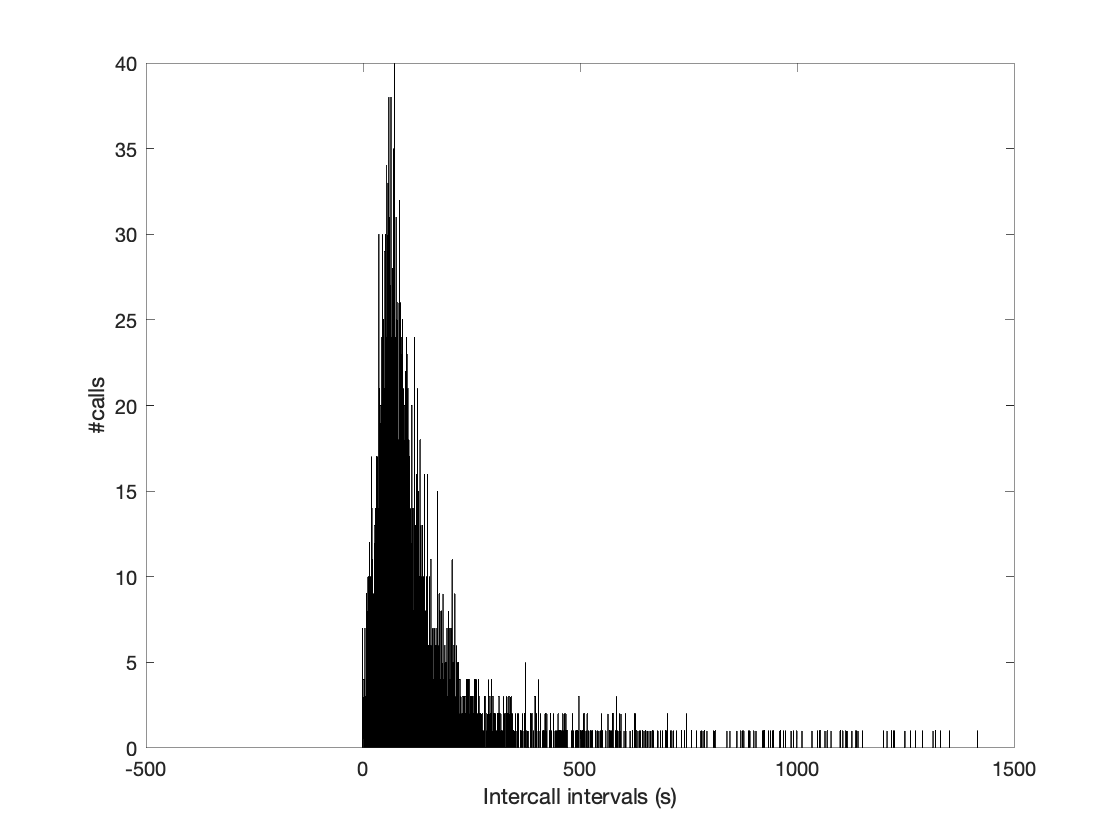

ICI = [InterCallInterval{:}]/10^3; % values in seconds
histogram(ICI,'BinWidth',1)
xlim([-500 1500])
xlabel('Intercall intervals (s)')
ylabel('#calls')

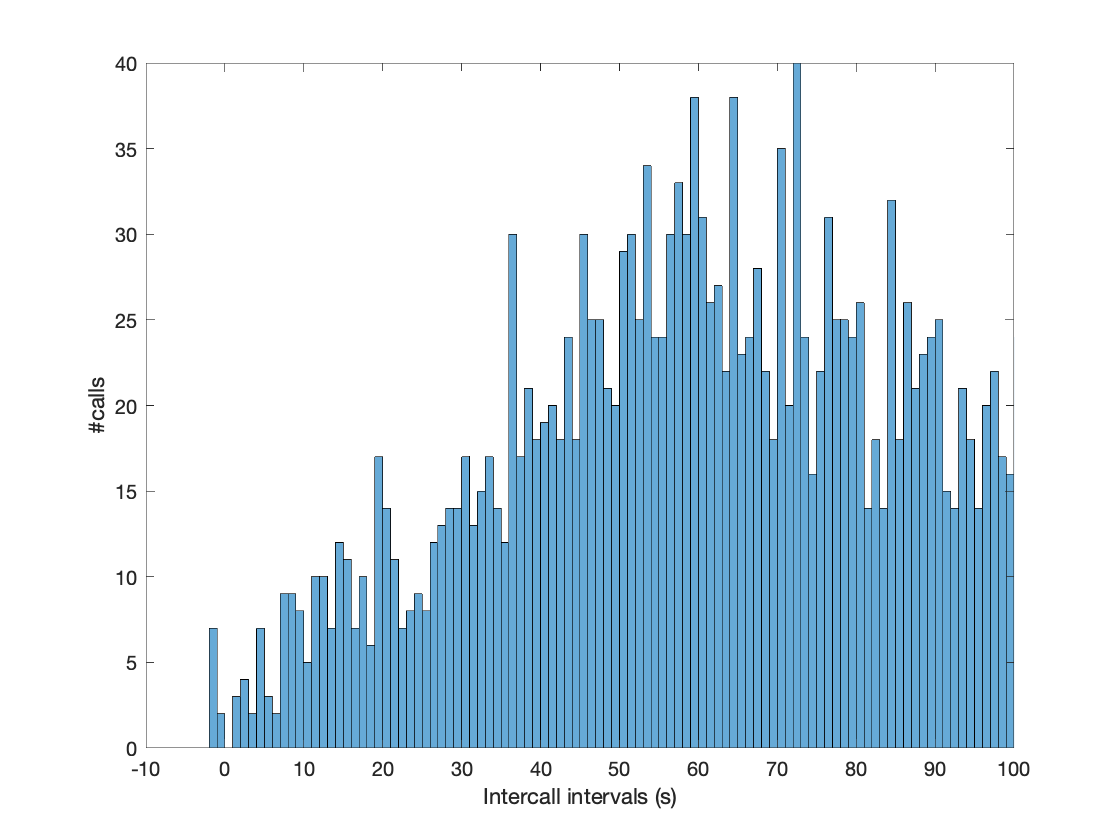

histogram(ICI,'BinWidth',1)
xlim([-10 100])
xlabel('Intercall intervals (s)')
ylabel('#calls')

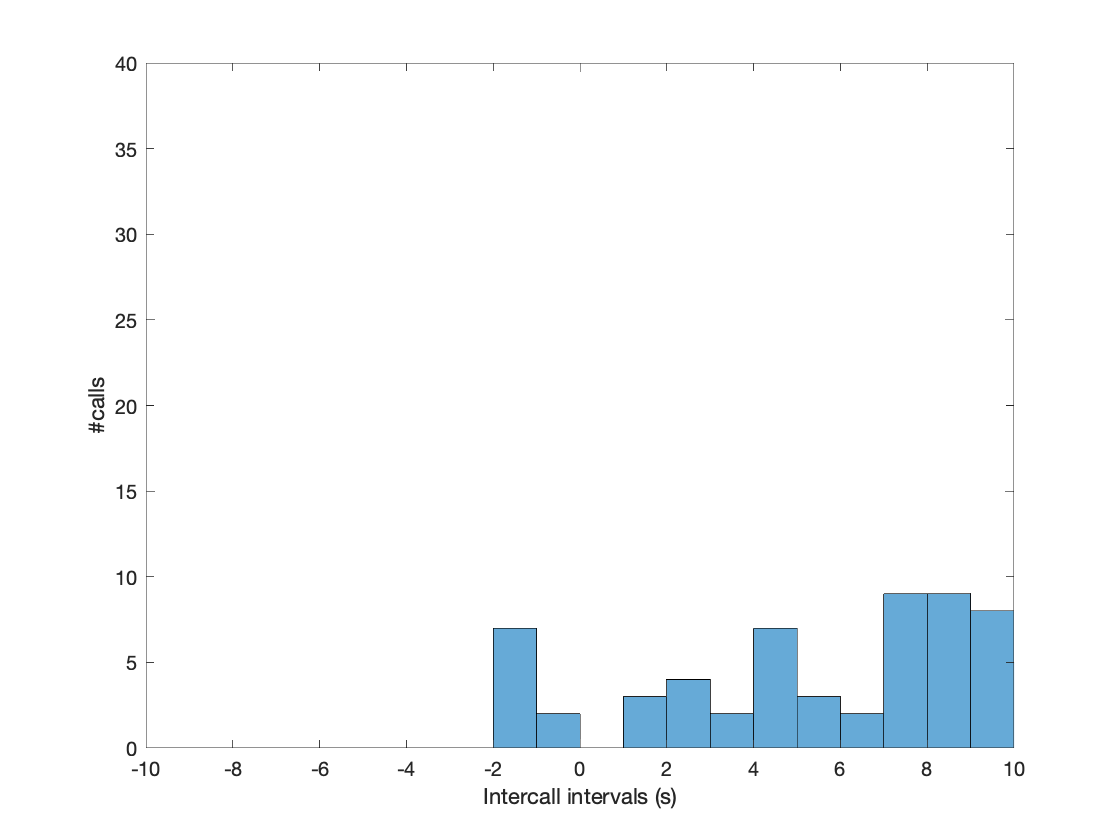

histogram(ICI,'BinWidth',1)
xlim([-10 10])
xlabel('Intercall intervals (s)')
ylabel('#calls')

nanmean(ICI)

ans = 156.6559

nanmedian(ICI)

ans = 90.9343

## Explore the time to get the reward

fprintf(1,'*** Gathering Data for timing of reward ***\n')

*** Gathering Data for timing of reward ***


BasePath = '/Volumes/server_home/users/JulieE/LMC';
Time2Reward = cell(1,10^3); % initialize the list to 1000
Time2RewardFront = cell(1,10^3); % initialize the list to 1000
Time2RewardBack = cell(1,10^3); % initialize the list to 1000
Time2RewardBoth = cell(1,10^3); % initialize the list to 1000
ExpFolders = dir(fullfile(BasePath,'LMC_Co*'));
NDays = 0; % counter for single days
for ee=1:length(ExpFolders)
    fprintf(1, '\n  -> Looking into  %s...\n ', fullfile(ExpFolders(ee).folder,ExpFolders(ee).name))
    DateFolders = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name, 'audio','20*'));
    for dd=1:length(DateFolders)
        fprintf(1, '   %s\n', DateFolders(dd).name);
        DataFileStruc = dir(fullfile(DateFolders(dd).folder, DateFolders(dd).name, '*VocTrigger_events.txt'));
        if ~isempty(DataFileStruc)
            for exx=1:length(DataFileStruc)
                NDays=NDays+1;
                fprintf(1,'*** Getting events for that day ***\n');
                Fid_Data = fopen(fullfile(DataFileStruc(exx).folder,DataFileStruc(exx).name));
                EventsHeader = textscan(Fid_Data, '%s\t%s\t%s\t%s\t%s\t%s\t%s\n',1);
                for hh=1:length(EventsHeader)
                    if strfind(EventsHeader{hh}{1}, 'SampleStamp')
                        EventsStampCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'Type')
                        EventsEventTypeCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'FoodPortFront')
                        EventsFoodPortFrontCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'FoodPortBack')
                        EventsFoodPortBackCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'TimeStamp(s)')
                        EventsTimeCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'Delay2Reward')
                        EventsRewardCol = hh;
                    end
                end
                Events = textscan(Fid_Data, '%s\t%f\t%s\t%s\t%f\t%f\t%f');
                fclose(Fid_Data);
                VocId = find(strcmp('Vocalization', Events{EventsEventTypeCol}));
                ReTriggerVocId = intersect(find(~isnan(Events{EventsRewardCol}) .* ~isinf(Events{EventsRewardCol})), VocId);
                ReTriggerVocFrontPId = intersect(find(~isnan(Events{EventsRewardCol}) .* (Events{EventsFoodPortFrontCol}==1) .* (Events{EventsFoodPortBackCol}==0)), VocId);
                ReTriggerVocBackPId = intersect(find(~isnan(Events{EventsRewardCol}) .* (Events{EventsFoodPortBackCol}==1) .* (Events{EventsFoodPortFrontCol}==0)), VocId);
                ReTriggerVocBothPId = intersect(find(~isnan(Events{EventsRewardCol}) .* (Events{EventsFoodPortBackCol}==1) .* (Events{EventsFoodPortFrontCol}==1)), VocId);
                Time2Reward{NDays} = Events{EventsRewardCol}(ReTriggerVocId)';
                Time2RewardFront{NDays} = Events{EventsRewardCol}(ReTriggerVocFrontPId)';
                Time2RewardBack{NDays} = Events{EventsRewardCol}(ReTriggerVocBackPId)';
                Time2RewardBoth{NDays} = Events{EventsRewardCol}(ReTriggerVocBothPId)';
                
            end
            
            
        end
    end
end


  -> Looking into  /Volumes/server_home/users/JulieE/LMC/LMC_CoEd...
 

   20190506


*** Getting events for that day ***


   20190507


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190508


*** Getting events for that day ***


   20190509


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190510


*** Getting events for that day ***


   20190513


*** Getting events for that day ***


   20190514


*** Getting events for that day ***


   20190515


*** Getting events for that day ***


   20190516


*** Getting events for that day ***


   20190517


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190520


*** Getting events for that day ***


   20190521


*** Getting events for that day ***


   20190522


*** Getting events for that day ***


   20190523


*** Getting events for that day ***


   20190524


*** Getting events for that day ***


   20190603


*** Getting events for that day ***


   20190604


*** Getting events for that day ***


   20190605


*** Getting events for that day ***
*** Getting events for that day ***


   20190606


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190607


*** Getting events for that day ***


   20190610


*** Getting events for that day ***


   20190611


*** Getting events for that day ***


   20190612


*** Getting events for that day ***
*** Getting events for that day ***


   20190613


*** Getting events for that day ***


   20190614


*** Getting events for that day ***


   20190616


*** Getting events for that day ***


   20190617


*** Getting events for that day ***


   20190618


*** Getting events for that day ***


   20190619


*** Getting events for that day ***


   20190620


*** Getting events for that day ***


   20190621


*** Getting events for that day ***


   20190622


*** Getting events for that day ***


   20190623


*** Getting events for that day ***


   20190624


*** Getting events for that day ***


   20190625


*** Getting events for that day ***


   20190626


*** Getting events for that day ***


   20190627


*** Getting events for that day ***


   20190628


*** Getting events for that day ***


   20190629


*** Getting events for that day ***


   20190630


*** Getting events for that day ***


   20190701


*** Getting events for that day ***
*** Getting events for that day ***


   20190702


*** Getting events for that day ***


   20190703


*** Getting events for that day ***


   20190704


*** Getting events for that day ***


   20190705


*** Getting events for that day ***


   20190706


*** Getting events for that day ***


   20190707


*** Getting events for that day ***


   20190708


*** Getting events for that day ***


   20190709


*** Getting events for that day ***


   20190710


*** Getting events for that day ***


   20190711


*** Getting events for that day ***


   20190712


*** Getting events for that day ***


   20200108


*** Getting events for that day ***


   20200109


*** Getting events for that day ***


Time2Reward = Time2Reward(1:NDays);
Time2RewardFront = Time2RewardFront(1:NDays);
Time2RewardBack = Time2RewardBack(1:NDays);
Time2RewardBoth = Time2RewardBoth(1:NDays);

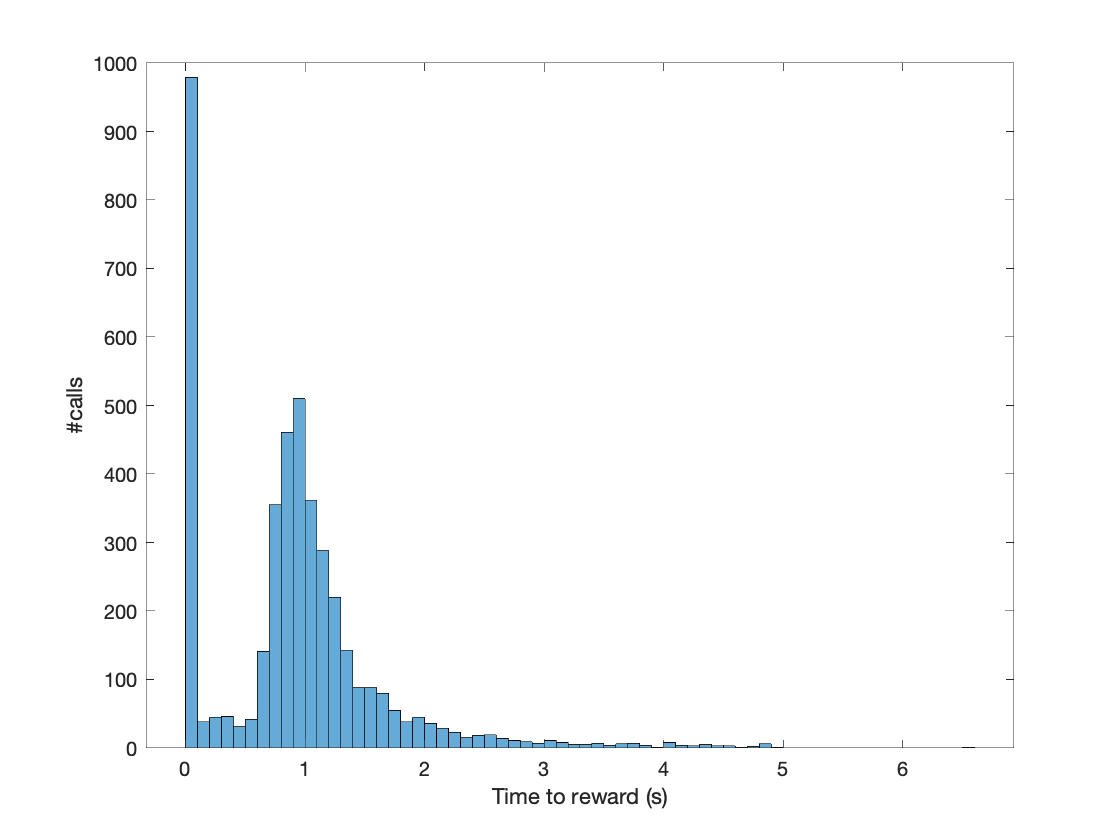

T2R = [Time2Reward{:}];
histogram(T2R,'BinWidth',0.1)
xlabel('Time to reward (s)')
ylabel('#calls')

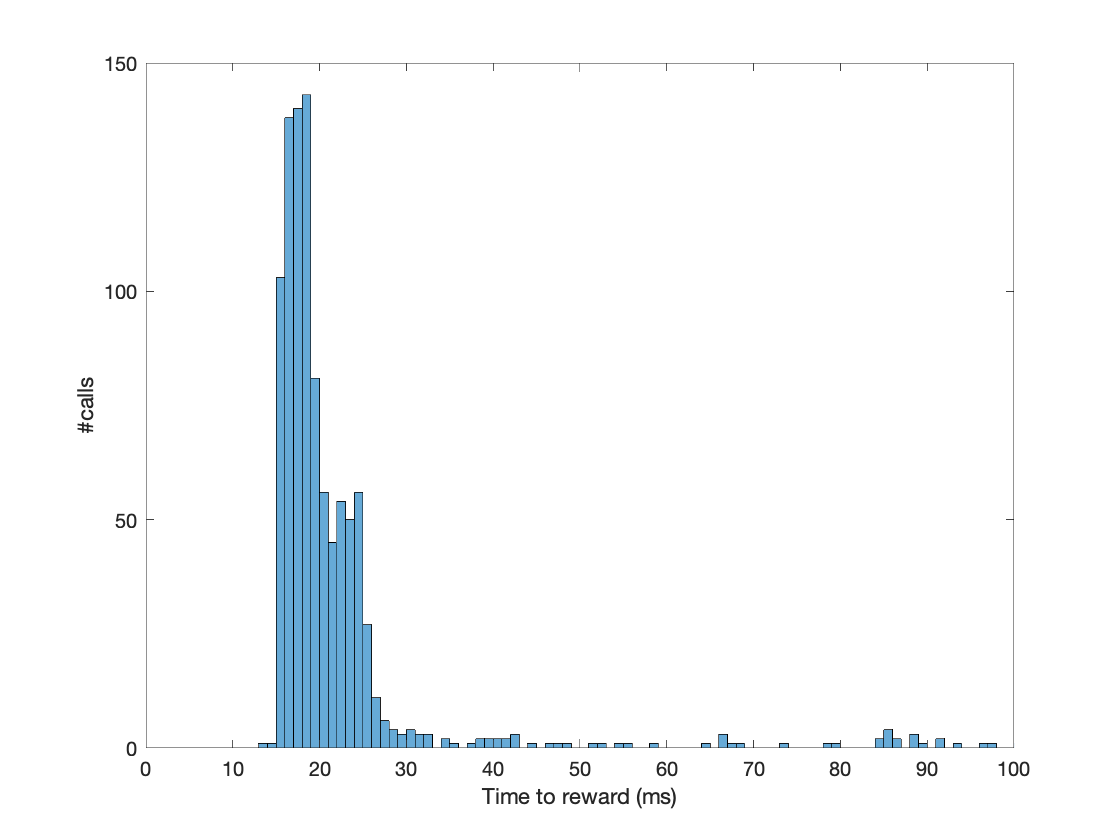


histogram(T2R*1000,'BinWidth',1)
xlim([0 100])
xlabel('Time to reward (ms)')
ylabel('#calls')

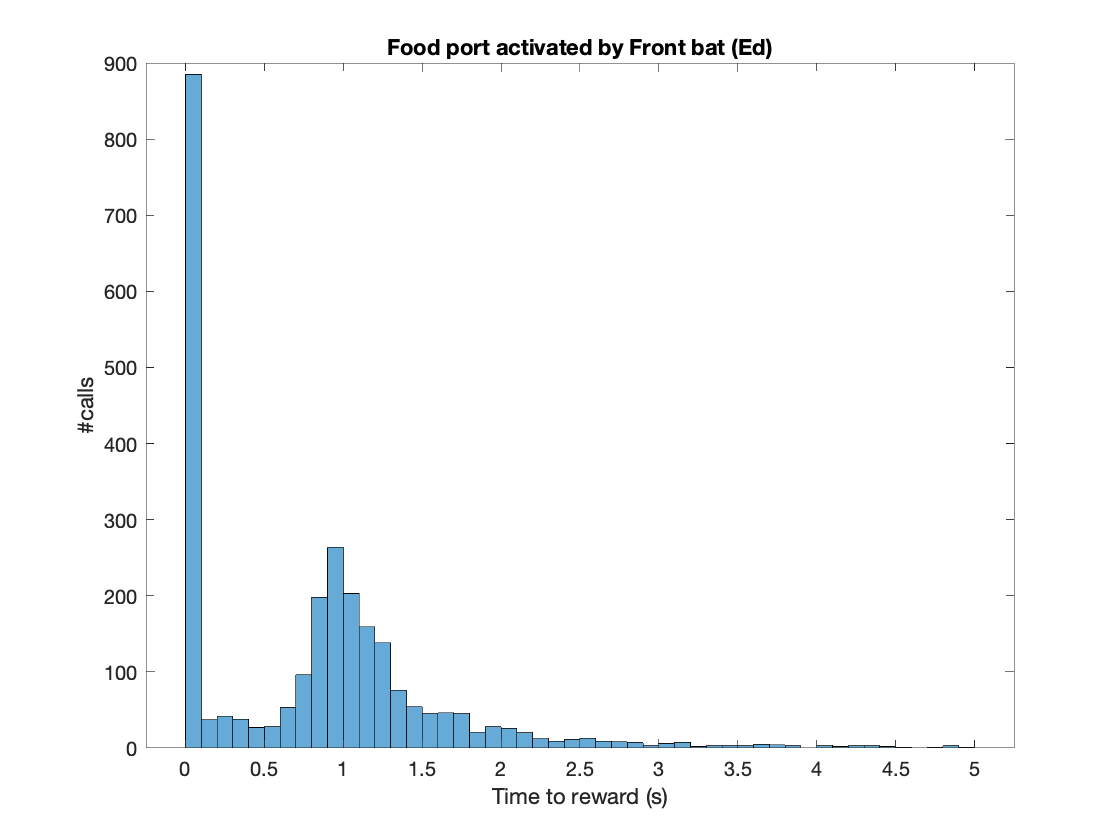


T2RF = [Time2RewardFront{:}];
histogram(T2RF,'BinWidth',0.1)
xlabel('Time to reward (s)')
ylabel('#calls')
title('Food port activated by Front bat (Ed)')

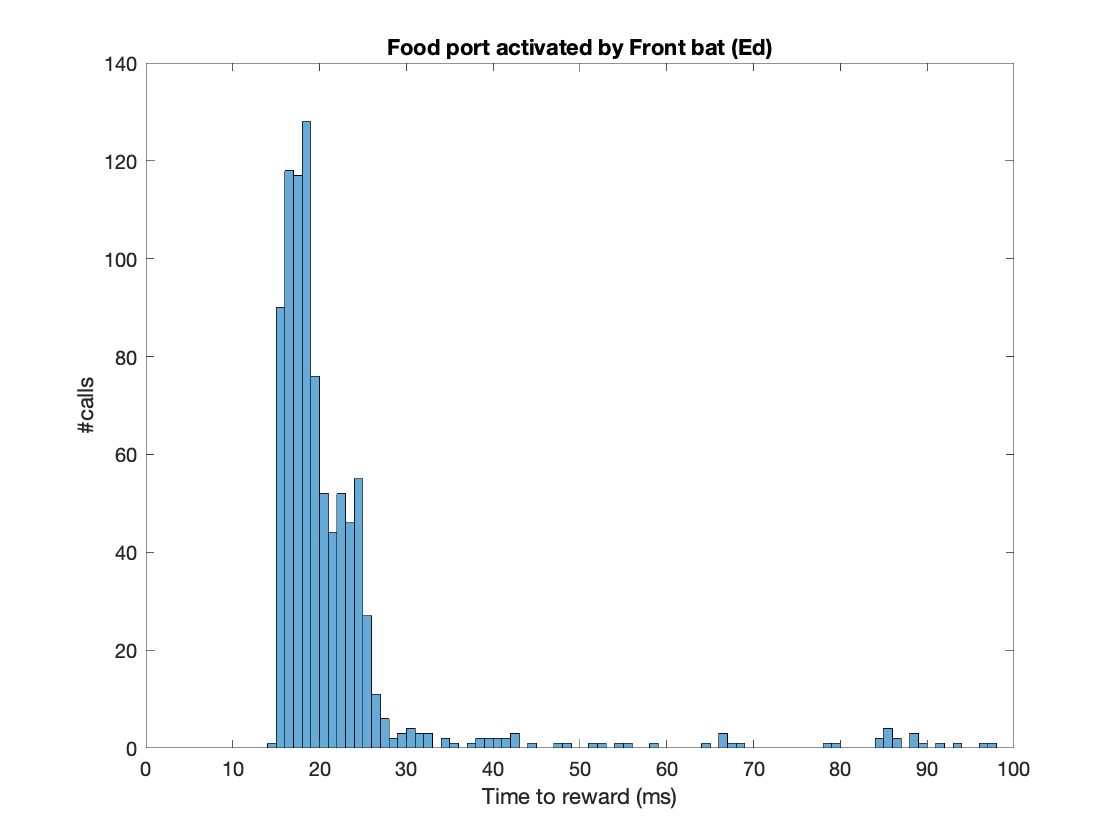


histogram(T2RF*1000,'BinWidth',1)
xlim([0 100])
xlabel('Time to reward (ms)')
ylabel('#calls')
title('Food port activated by Front bat (Ed)')

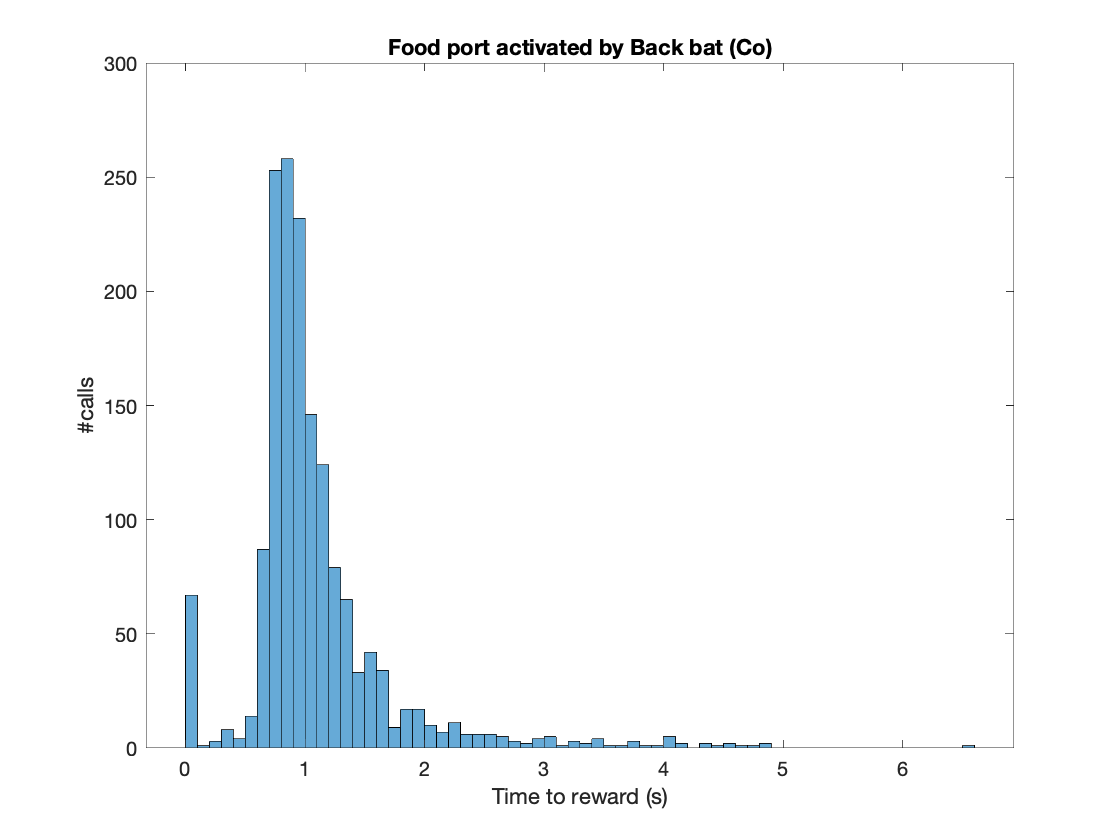


T2RB = [Time2RewardBack{:}];
histogram(T2RB,'BinWidth',0.1)
xlabel('Time to reward (s)')
ylabel('#calls')
title('Food port activated by Back bat (Co)')

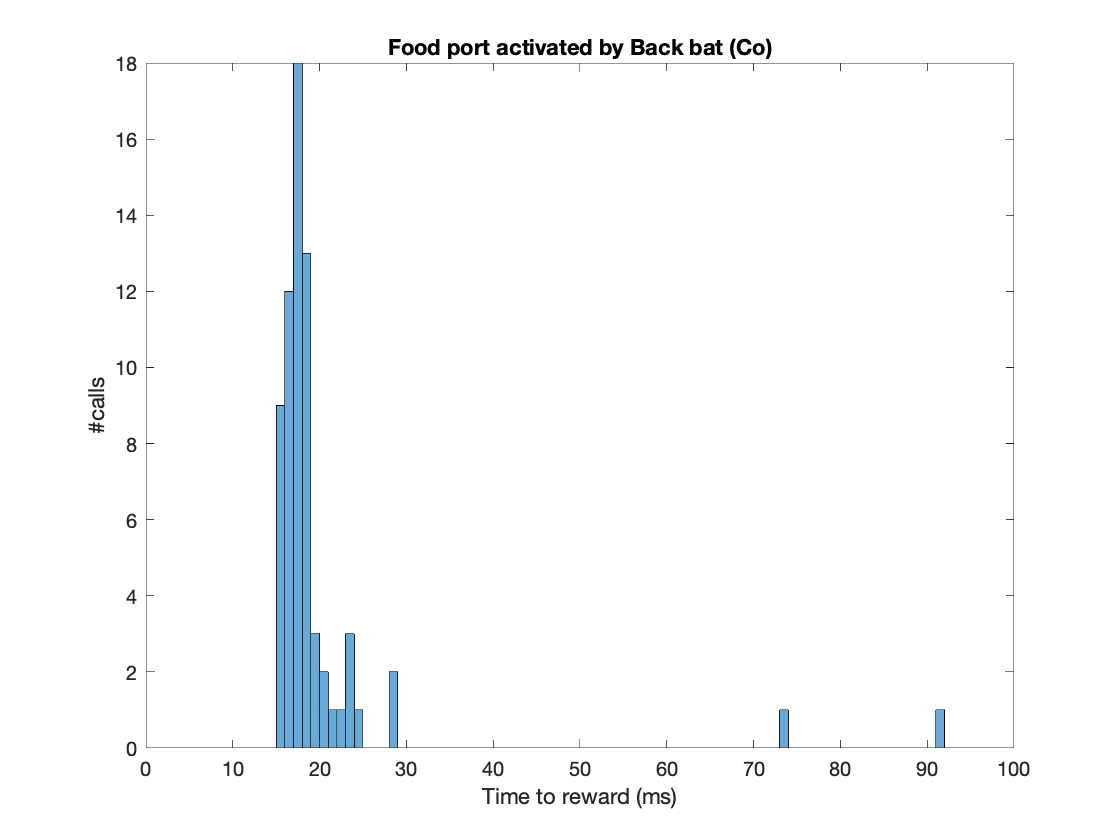


histogram(T2RB*1000,'BinWidth',1)
xlim([0 100])
xlabel('Time to reward (ms)')
ylabel('#calls')
title('Food port activated by Back bat (Co)')

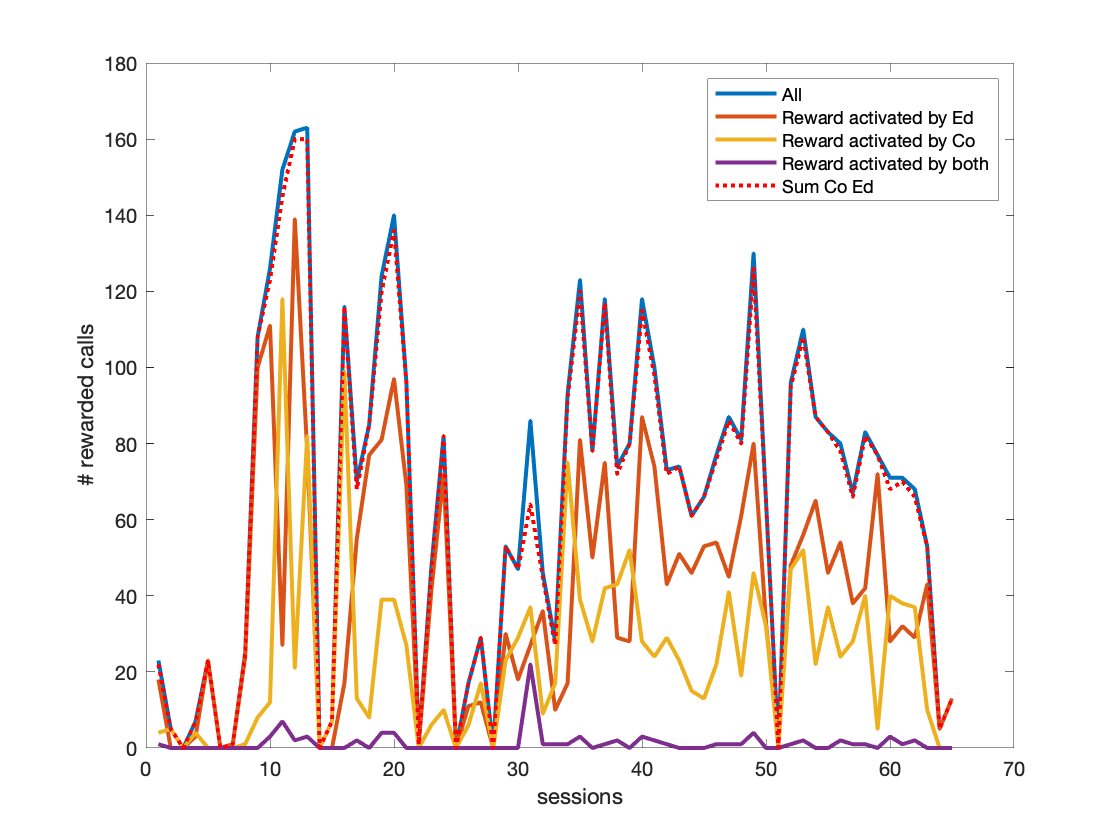


NumRe = cellfun(@length,Time2Reward);
NumReFr = cellfun(@length,Time2RewardFront);
NumReBa = cellfun(@length,Time2RewardBack);
NumReBoth = cellfun(@length,Time2RewardBoth);

plot([NumRe; NumReFr; NumReBa; NumReBoth]', 'LineWidth',2)
hold on
plot(NumReFr + NumReBa, 'r:', 'LineWidth',2)
hold off
legend({'All' 'Reward activated by Ed' 'Reward activated by Co' 'Reward activated by both' 'Sum Co Ed'})
ylabel('# rewarded calls')
xlabel('sessions')